% Grey World Assumption 

img = imread("db1_03.jpg");

% Separate color channels
R = img(:,:,1);
G = img(:,:,2);
B = img(:,:,3);

% Calculate average color
averageColor = (mean(R(:)) + mean(G(:)) + mean(B(:))) / 3;

% Calculate correction factor
correctionFactor = averageColor ./ [mean(R(:)), mean(G(:)), mean(B(:))];

% Apply correction to each channel
correctedImg = cat(3, R .* correctionFactor(1), G .* correctionFactor(2), B .* correctionFactor(3));


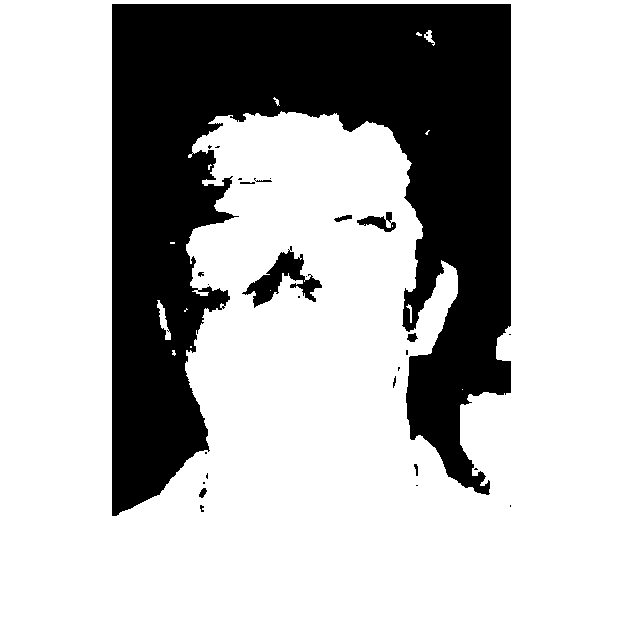

% Face mask

% Create a segmented picture 

imgRGB = imread("db1_02.jpg");

imgYCrBr = rgb2ycbcr(imgRGB); 

imgYCrBr = im2double(imgYCrBr(:,:,2));

Tresh = graythresh(imgYCrBr);

TreshBin = imbinarize(imgYCrBr,Tresh);

imshow(TreshBin)


kernel = ones(3,3)/(3*3);

bfilt = imfilter(imgYCrBr,kernel,'symmetric'); 

b_thresh = bfilt < Tresh;

r1=10;

SE = strel('sphere',r1);

TreshBin2 = imopen(b_thresh,SE);

TreshBin3 = imclose(TreshBin2,SE);

face_mask = (1 - TreshBin3)

face_mask =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0 

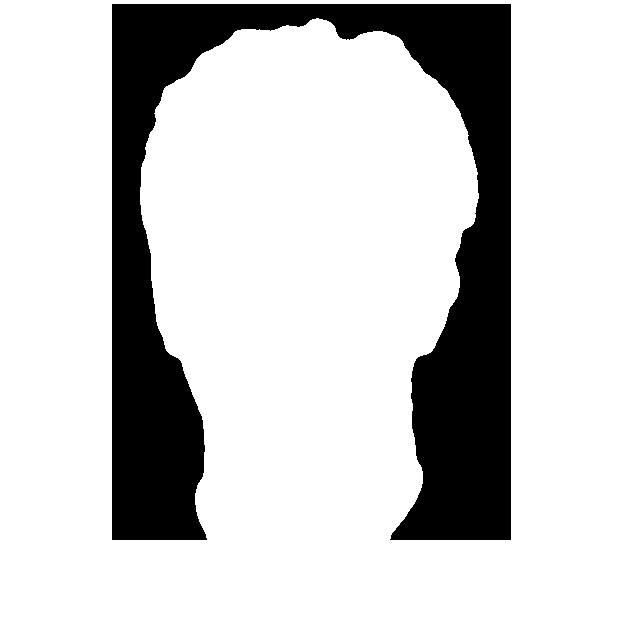


imshow(face_mask)


% Open and close to remove artificats in the face and background 

% Eye mask from https://ieeexplore.ieee.org/stamp/stamp.jsp?tp=&arnumber=476009

imgRGB = imread("db1_02.jpg");

imgRGB = 536×399×3 uint8 array
imgRGB(:,:,1) =

   197   196   194   193   194   196   196   194   195   196   197   198   198   198   199   200   199   200   201   202   202   201   201   202   201   202   202   203   203   203   202   201   202   200   199   201   200   199   203   199   203   203   202   201   200   199   200   200   202   202   202   203   203   202   203   205   203   208   210   207   204   205   205   204   205   206   206   205   204   204   206   207   208   208   207   207   207   207   206   206   206   204   203   203   204   206   206   206   208   205   205   204   203   204   206   204   207   206   207   207   205   206   208   207   205   205   205   205   208   208   209   208   207   206   206   207   207   207   210   213   208   205   205   208   209   208   209   211   208   208   209   208   208   208   208   209   211   209   209   211   209   205   205   209   210   209   209   209   209   209   209   208   209   210   208   206   207   210   2

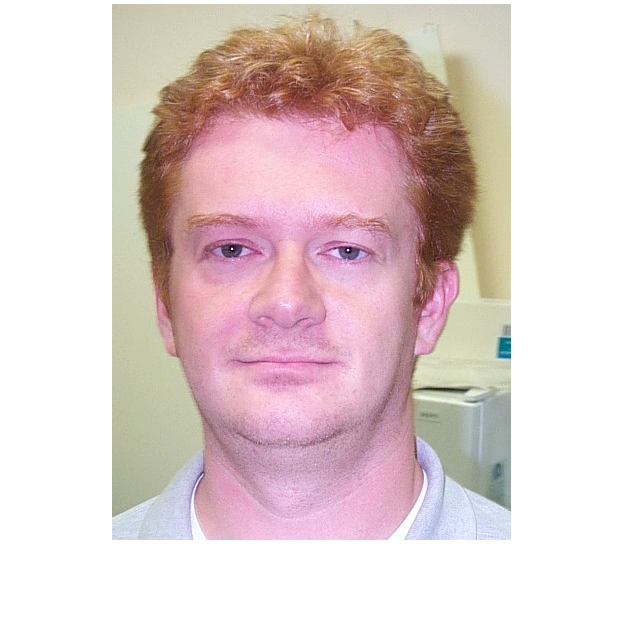


imshow(imgRGB);

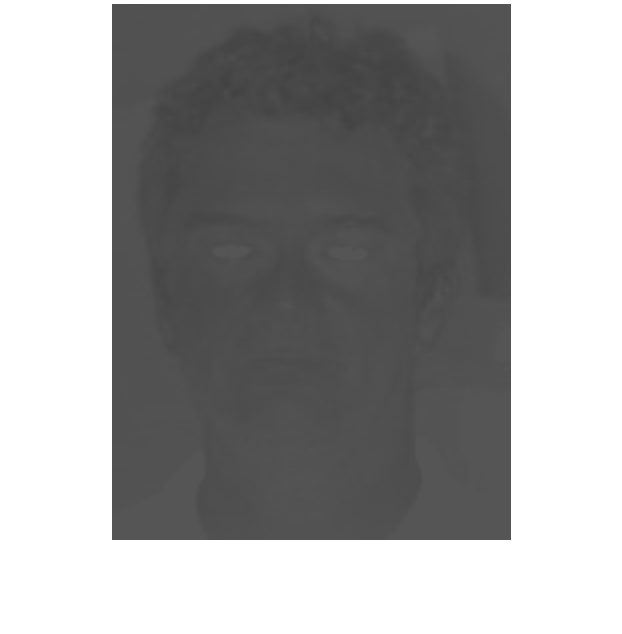


imgYCrBr = rgb2ycbcr(imgRGB);

LumChan = imgYCrBr(:,:,1);
BlueChan = imgYCrBr(:,:,2);
RedChan = imgYCrBr(:,:,3);

CR_tilde_2 = (255 - RedChan); 

CB2 = (BlueChan);

CR_Div_CB = BlueChan ./ RedChan; 

EyeMapC = (1/3).*(CB2 + CR_tilde_2 + CR_Div_CB);
imshow(EyeMapC)

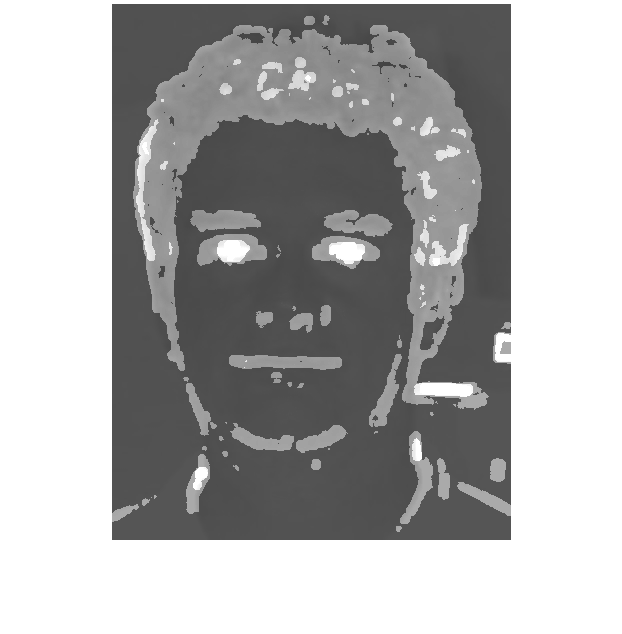


StructureBallSE = offsetstrel('ball',5,5);
Dialation = imdilate(LumChan,StructureBallSE); 

Erosion = imerode(LumChan,StructureBallSE);

EyeMapL = Dialation ./ (Erosion + 1);

EyeMapTotal = EyeMapC .* EyeMapL; 

imshow(EyeMapTotal);

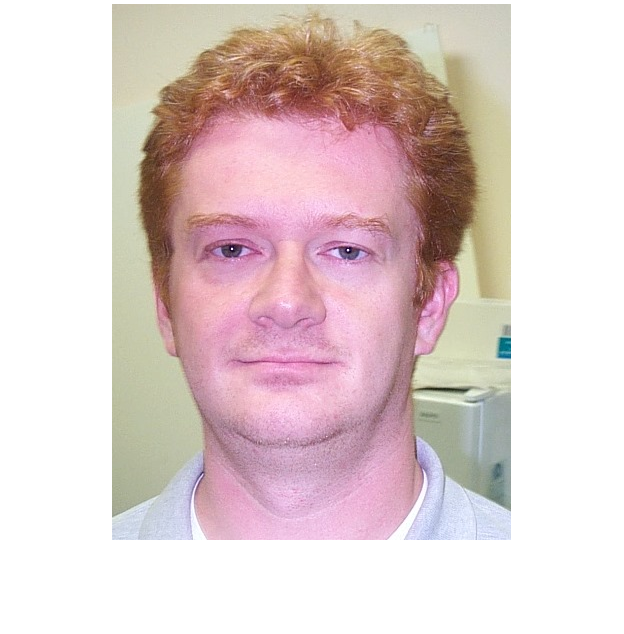

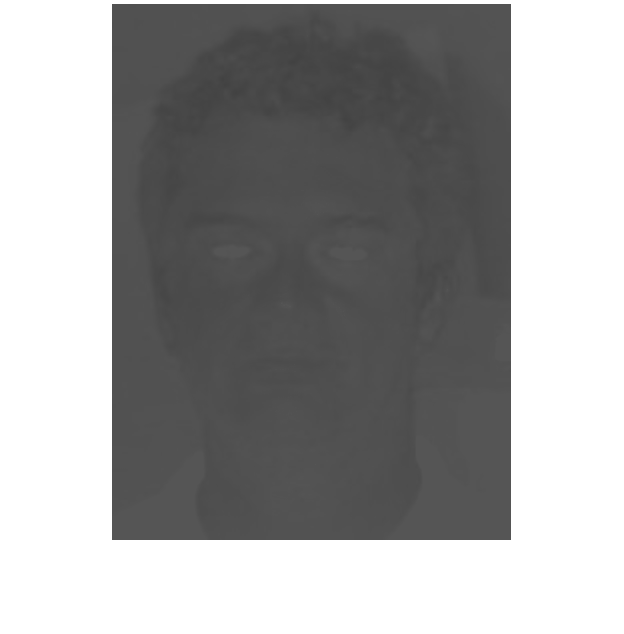

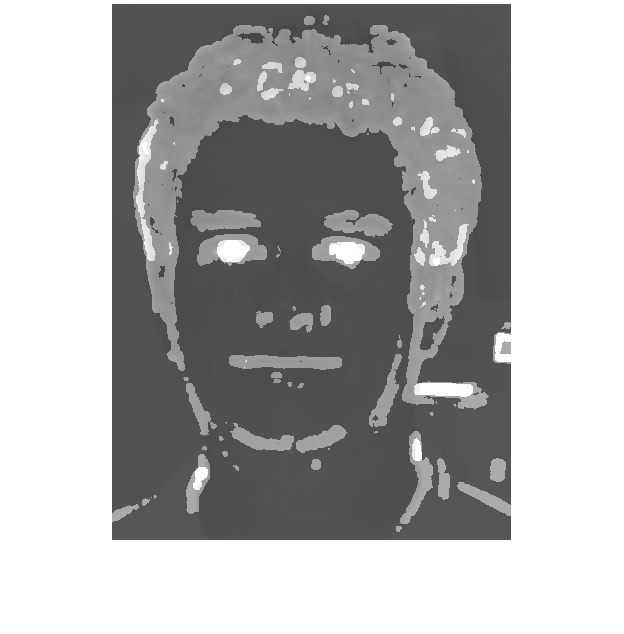

% Blandat 

imgRGB = imread("db1_01.jpg")


imshow(imgRGB);

imgYCrBr = rgb2ycbcr(imgRGB)

%imshow(imgYCrBr(:,:,1)) %Luminance 
%imshow(imgYCrBr(:,:,2)) % Blue chrome 
%imshow(imgYCrBr(:,:,3)) % Red chrome

% Red channel
imgGreyTreshRED = graythresh(imgYCrBr(:,:,3));

RedChannel = imbinarize(imgYCrBr(:,:,3),imgGreyTreshRED);

% Blue channel
imgGreyTreshBLUE = graythresh(imgYCrBr(:,:,2));

BlueChannel = imbinarize(imgYCrBr(:,:,2),imgGreyTreshBLUE)

% Combination 

EyeMap = ((BlueChannel.^2)+(max(RedChannel)./(min(RedChannel)))^2)+(BlueChannel ./ RedChannel)

EyeMap = EyeMap*(1/3);

imshow(EyeMap)

%DiviedImage = BlueChannel.^2 + RedChannel.^2; 

%imshow(DiviedImage)

% Luminance grey treshold 
imgGreyTreshLu = graythresh(imgYCrBr(:,:,1));

LuChannel = imbinarize(imgYCrBr(:,:,1),imgGreyTreshLu);

% Combination of luminance with chromes 
final = DiviedImage .* LuChannel;

imshow(final)
